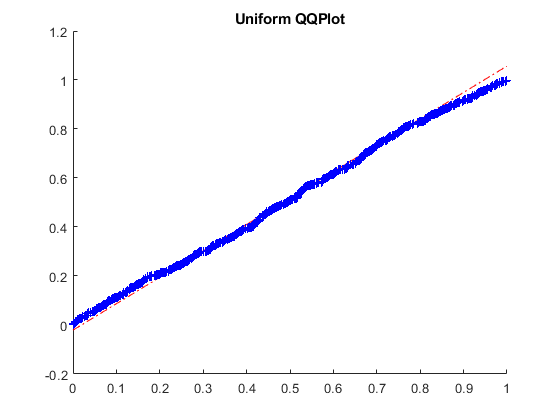

clear all;
close all;

a = 16807;
m = 2^31 - 1;
s = 1;
k = 1000; %number of rand nums to generate
u = rand(1,k); %uniform vector for comparison
fin = fopen('seq1.txt','r');
x = fscanf(fin,'%f');
fclose(fin);
qqplot(x,u);
title('Uniform QQPlot');
xlabel('');
ylabel('');

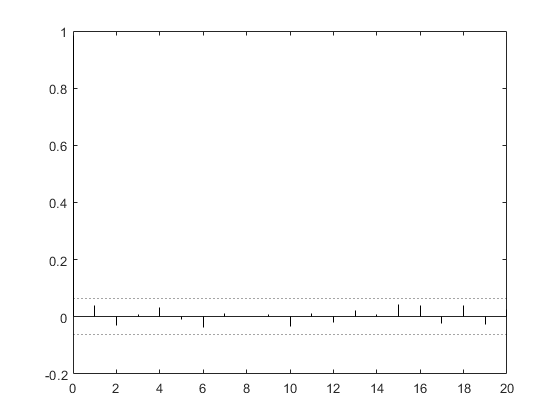

[ac,lags,bounds] = autocorr(x);
stem(lags,ac,'Marker','none','Color','k');
hold on
yline(bounds(1),':k');
yline(bounds(2),':k');
hold off

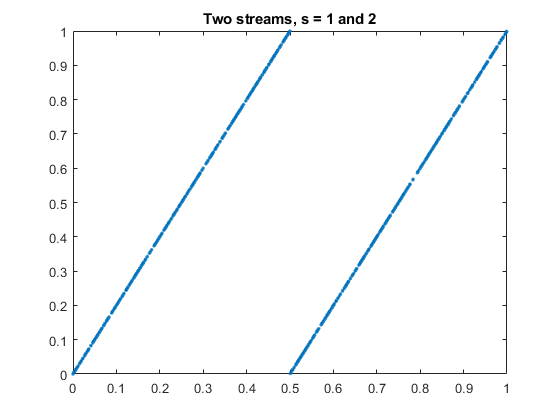

fig = figure;
% for i=1:9
%     shifted_data = circshift(x,-100*i);
%     subplot(3,3,i);
%     plot(x,shifted_data,'.');
%     title(['h = ' num2str(100*i)]);
%     axs = axes(fig,'Visible','off');
%     %axs.XLabel.Visible = 'on';
%     %xlabel('(d) Lag plots');
% end

fin = fopen('seq2.txt','r');
y = fscanf(fin,'%f');
fclose(fin);

x = x(1:length(y));
plot(x,y,'.');